Tarea 3: entrenamiento del algoritmo K-means

addpath('./datos')
addpath('./funciones')

Con traindata.mat

load('traindata.mat')
if isempty(gcp('nocreate'))
parpool;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 8).


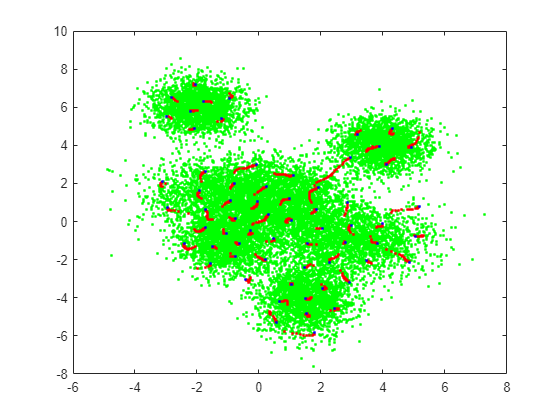


[VQ vDist no_asig] = Kmeans(traindata, 6, [], 0.001, 1);

Representa cómo varía la distorsión obtenida, vDist, en función de la iteración

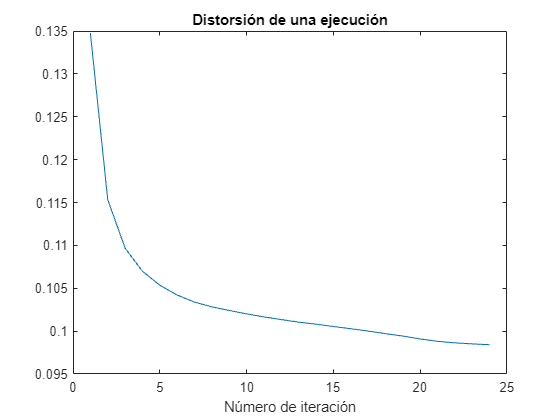

plot(vDist)
title('Distorsión de una ejecución')
xlabel('Número de iteración')
ylabel(' ')

Ejecuta el algoritmo Kmeans 20 veces . Guarda el tiempo de ejecución y la distorsión de la última iteración de cada ejecución. Represéntalos gráficamente. (Ayuda: funciones Matlab clock y etime)

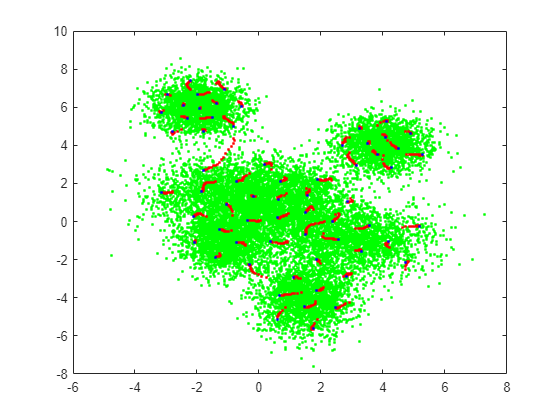

load('traindata.mat')
if isempty(gcp('nocreate'))
parpool;
end

for i = 1:20
  horaInicial = clock;
  [VQ vDist no_asig] = Kmeans(traindata, 6, [], 0.001, 1);
  horaFinal = clock;
  vectorDistorsion(i,:) = vDist(length(vDist));
  vectorHoras(i,:) = etime(horaFinal, horaInicial);
end

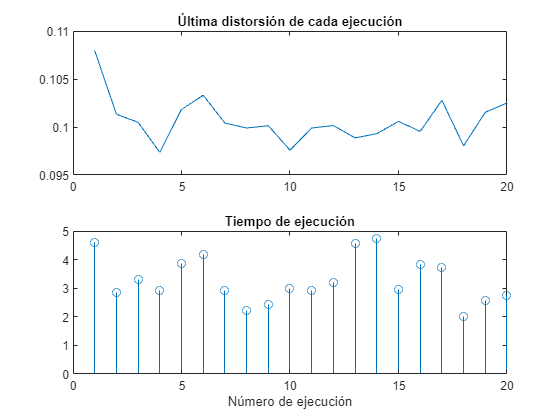

subplot(2,1,1);
  plot(vectorDistorsion)
  title('Última distorsión de cada ejecución')
  %xlabel('Número de ejecución')
subplot(2,1,2); 
  stem(vectorHoras)
  title('Tiempo de ejecución')
  xlabel('Número de ejecución')

Con tvg_training_20s.wav

addpath('./datos')
addpath('./funciones')

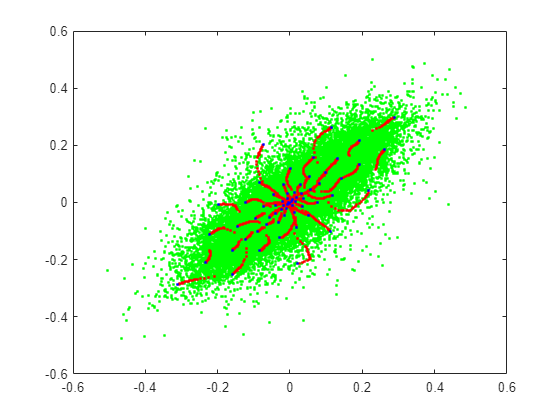

[valores_training, fs_training] = audioread('tvg_training_20s.wav');
columna = 0; %para cambiar entre una columna y otra
fila = 1;
for i=1:length(valores_training)
    if columna == 0 %impar
        training(fila, 1) = valores_training (i);
        columna = 1;
    else %par
        training(fila, 2) = valores_training (i);
        columna = 0;
        fila = fila + 1;
    end
end

% Diseñar un VQ de 6 bits (VQ6) con umbral=0.01

if isempty(gcp('nocreate'))
parpool;
end

[VQ6 vDist no_asig] = Kmeans(training, 6, [], 0.01, 1);

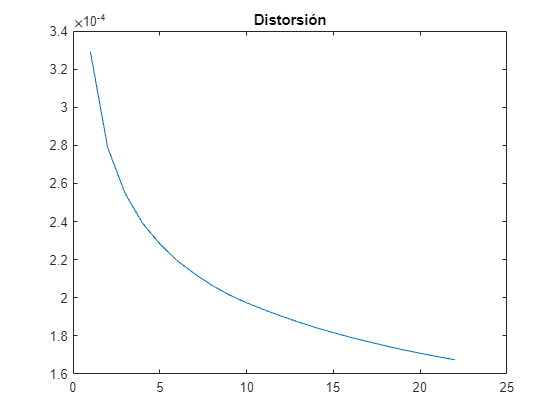

plot(vDist)
title('Distorsión')

[valores_test, fs_test] = audioread('tvg_test_20s.wav');
columna = 0; %para cambiar entre una columna y otra
fila = 1;
for i=1:length(valores_test)
    if columna == 0 %impar
        test(fila, 1) = valores_test (i);
        columna = 1;
    else %par
        test(fila, 2) = valores_test (i);
        columna = 0;
        fila = fila + 1;
    end
end

save Tarea3.mat
tiempoEjecucion = sum(vectorHoras)

tiempoEjecucion = 65.5910